# Train Voxel Classifier

## Getting a First Impression about the Data

### Load one of the data sets into memory

% Point to data folder
data_root = "/Users/amithkamath/data/mialab/";

%Alternative: Select one of the folders using a slider...

datafolder = data_root + "train" + filesep + "100307"; 
dataT1 = niftiread(datafolder + filesep + "T1native.nii.gz");
dataT2 = niftiread(datafolder + filesep + "T2native.nii.gz");
labels = categorical(niftiread(datafolder + filesep + "labels_native.nii.gz"));
native_mask=uint16(niftiread(datafolder + filesep + "Brainmasknative.nii.gz"));

Note that the individual data files can have different datatypes!

### Visualize Slices of the Data Set

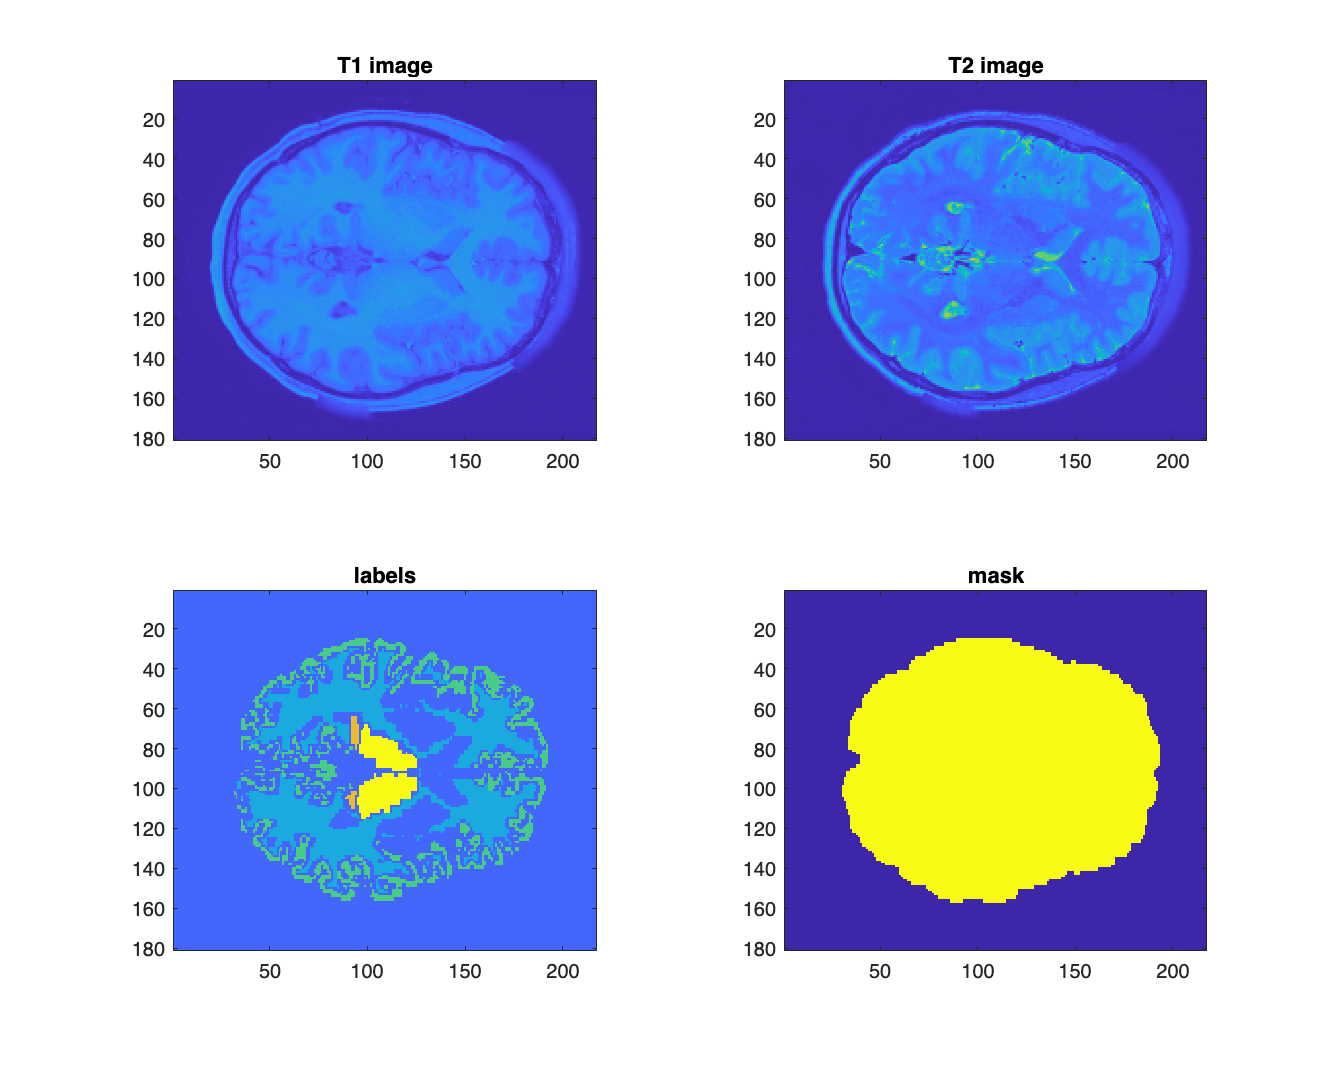

size(dataT1,3);
slice=73;
figure("Position",[0 0 1000 800])
tiledlayout(2,2)
nexttile
imagesc(dataT1(:,:,slice),[min(dataT1,[],"all") max(dataT1,[],"all")])
title("T1 image")
nexttile
imagesc(dataT2(:,:,slice),[min(dataT2,[],"all") max(dataT1,[],"all")])
title("T2 image")
nexttile
imagesc(double(labels(:,:,slice)),[0 5])
title("labels")
nexttile
imagesc(native_mask(:,:,slice))
title("mask")

### Visualize the complete volume

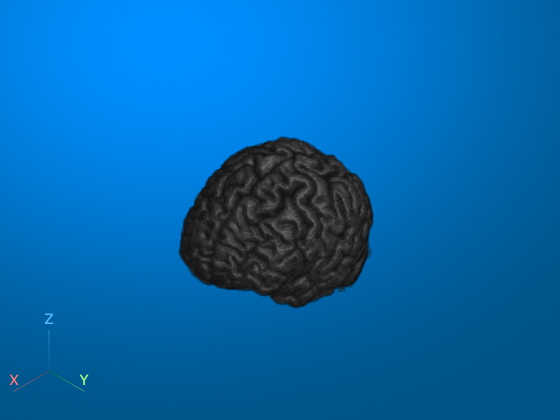

viewer = viewer3d(); %this is helpful if we would like to show more than just one volume
maskedT1=native_mask.*dataT1; %better to use the mask here
volshow(maskedT1, Parent=viewer); %display the volume in the selected viewer

## Batch preprocessing of training and test data

This processes the data in every sample folder and adds it to a feature table. The process of this preprocessing is described in detail in [Preprocessing.mlx](matlab:open('./Preprocessing.mlx'))


folder_train = dir(data_root + "train" + filesep);
folder_test = dir(data_root + "test" + filesep);
folder_atlas = fullfile(data_root, filesep, "atlas");

train_dataset=table;
% the 4 below is hard coded. would be a good to adapt this automatically to
% the output of the dir function.
for n = 4:12 % use length(folder_train) if you have enough memory to train.
    path=string(folder_train(n).folder) + filesep + string(folder_train(n).name)
    try
        tab = preprocess(path, folder_atlas);
        train_dataset=[train_dataset; tab];
    catch
        fprintf("Errored. Skipping volume.");
    end
end

path = "/Users/amithkamath/data/mialab/train/100307"

path = "/Users/amithkamath/data/mialab/train/100408"

Errored. Skipping volume.

path = "/Users/amithkamath/data/mialab/train/101107"

path = "/Users/amithkamath/data/mialab/train/101309"

Errored. Skipping volume.

path = "/Users/amithkamath/data/mialab/train/101915"

Errored. Skipping volume.

path = "/Users/amithkamath/data/mialab/train/103111"

path = "/Users/amithkamath/data/mialab/train/103414"

path = "/Users/amithkamath/data/mialab/train/103818"

path = "/Users/amithkamath/data/mialab/train/105014"


test_dataset=table;
for n=4:length(folder_test)
    path=string(folder_test(n).folder) + filesep + string(folder_test(n).name)
    try
        tab = preprocess(path, folder_atlas);
        test_dataset=[test_dataset; tab];
    catch
        fprintf("Errored. Skipping volume.");
    end
end

path = "/Users/amithkamath/data/mialab/test/117122"

path = "/Users/amithkamath/data/mialab/test/118528"

path = "/Users/amithkamath/data/mialab/test/118730"

path = "/Users/amithkamath/data/mialab/test/118932"

Errored. Skipping volume.

path = "/Users/amithkamath/data/mialab/test/120111"

path = "/Users/amithkamath/data/mialab/test/122317"

Errored. Skipping volume.

path = "/Users/amithkamath/data/mialab/test/122620"

Errored. Skipping volume.

path = "/Users/amithkamath/data/mialab/test/123117"

Errored. Skipping volume.

path = "/Users/amithkamath/data/mialab/test/123925"

Errored. Skipping volume.

path = "/Users/amithkamath/data/mialab/test/124422"

Errored. Skipping volume.

## Balancing of Data Sets

Before we train a Machine Learning algorithm, it is best practice to check the number of labels in the individual classes.

PS: Note that we have removed the masked voxels (class=0).

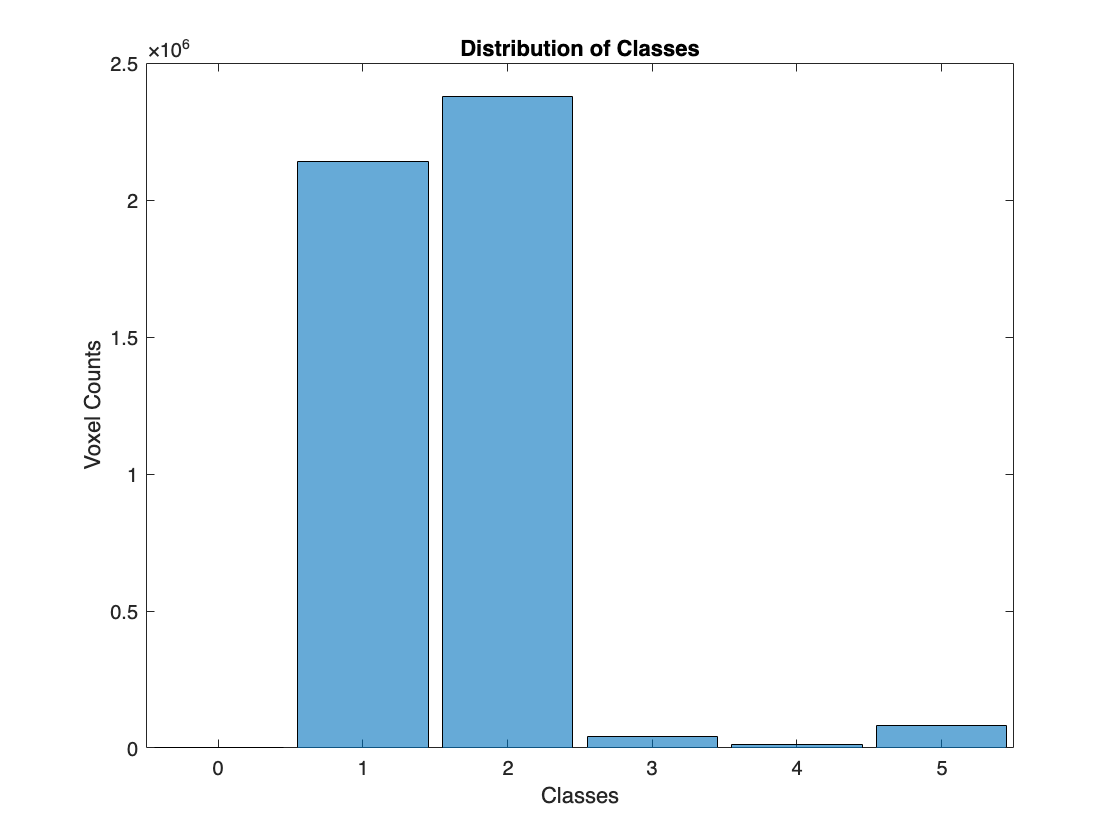

figure
histogram(train_dataset.label)
title("Distribution of Classes")
ylabel("Voxel Counts")
xlabel("Classes")

If the distribution of the classes is unbalanced this might lead to a biased prediction. This however depends on the specific algorithm. Some of them are less prone to unbalanced datasets than others.

Because we have a lot of voxels, we can afford to drop some of the observations. We thus balance the dataset by undersampling overrepresented classes. 

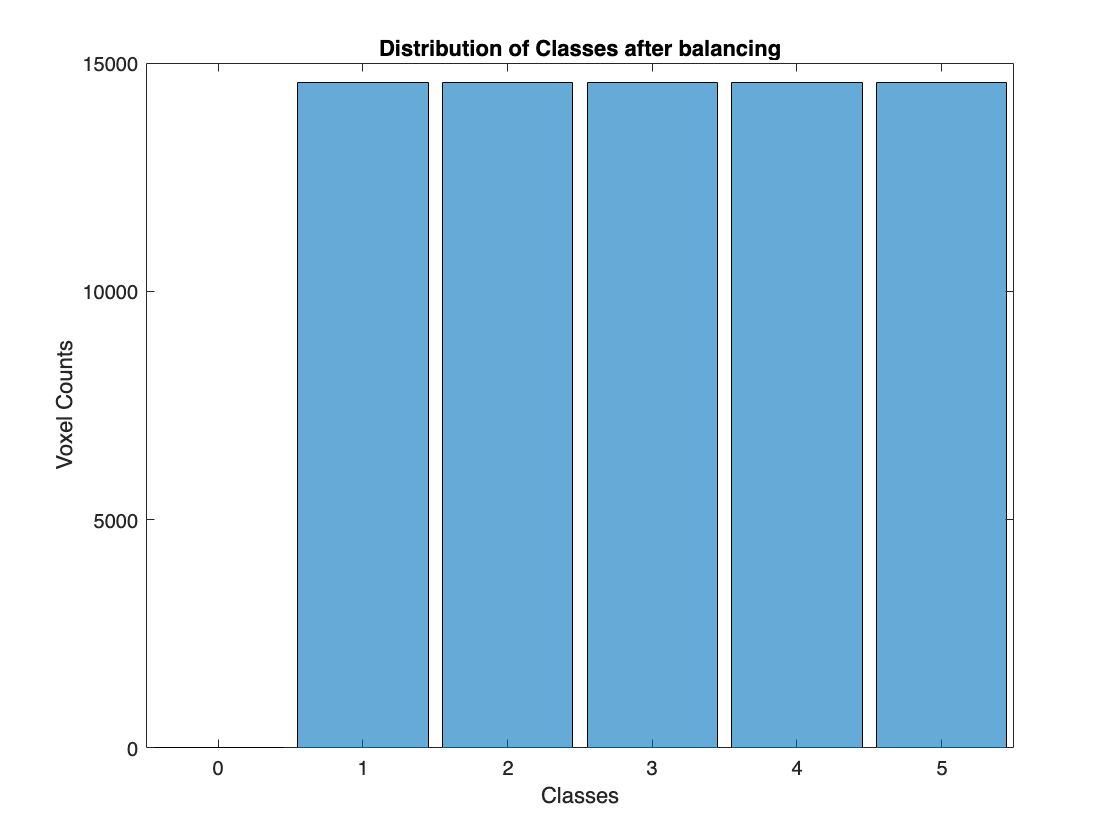

tab_train=balanceTable(train_dataset);
tab_test=balanceTable(test_dataset);

figure
histogram(tab_train.label)
title("Distribution of Classes after balancing")
ylabel("Voxel Counts")
xlabel("Classes")

## Training of a Classifier

open the classification learner:

classificationLearner

- start a new session from workspace

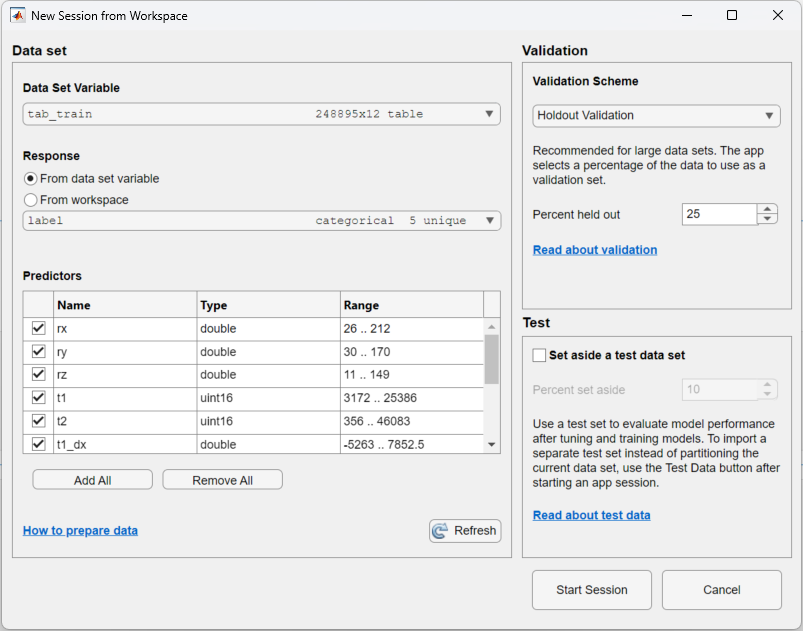

- Select models to train and click "Train all"

- Evaluate the Confusion Matrix

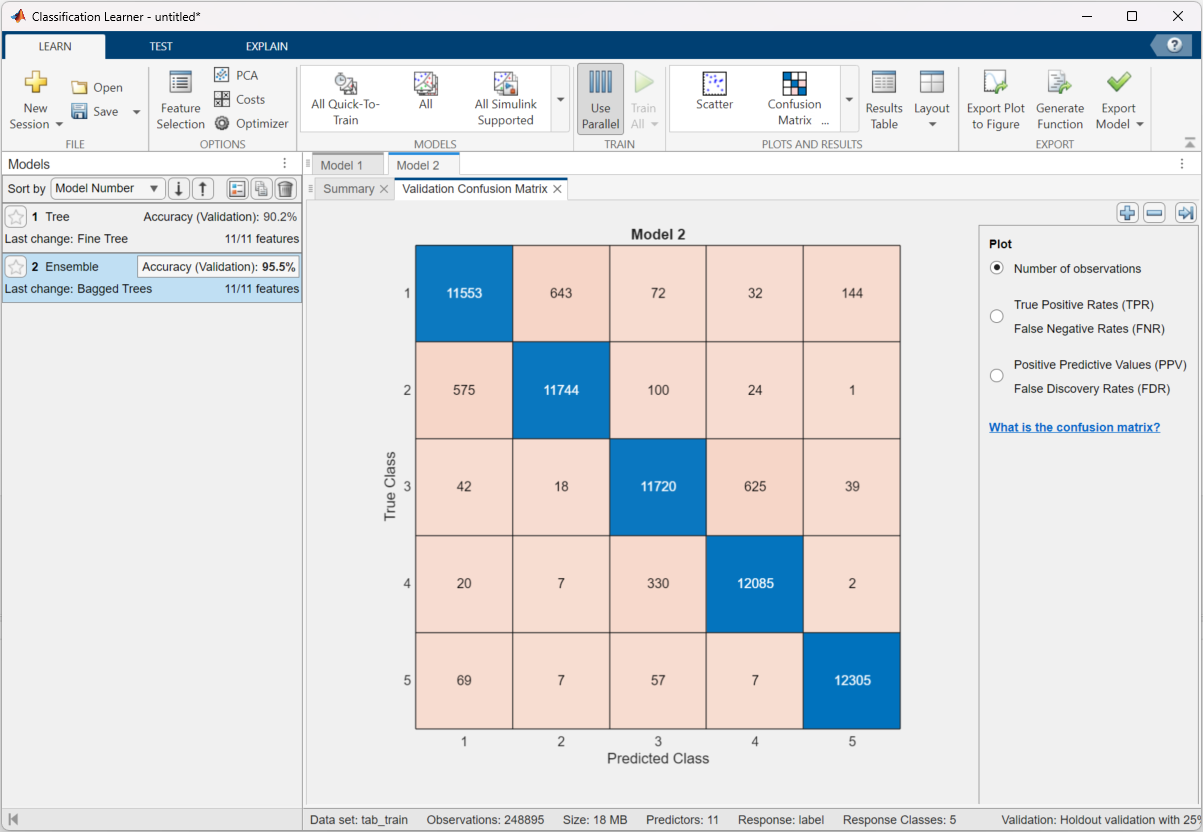

- Export the model

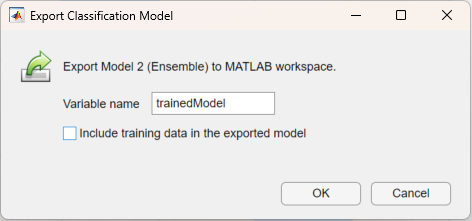

%train and test models using classification learner
%first try -> 91.3% test accuracy
%second try using bagged trees -> 93.4% on test data


## Apply this to a Specimen

%Preprocessing, Classification and then visualization in 3d volume...
tab=preprocess(data_root + "test" + filesep + "117122", folder_atlas);
[yfit,scores] = trainedModel.predictFcn(tab);

Unable to resolve the name 'trainedModel.predictFcn'.

%Assemble back into a 3D Volume (this is quite slow... but we cannot reshape it again because we miss the masked voxels?
img_class=zeros(197,233,189);
for n=1:height(tab)
    img_class(tab{n,"ry"},tab{n,"rx"},tab{n,"rz"})=yfit(n);
end

volumeViewer
%inspect volume labels by importing labeled volume from workspace

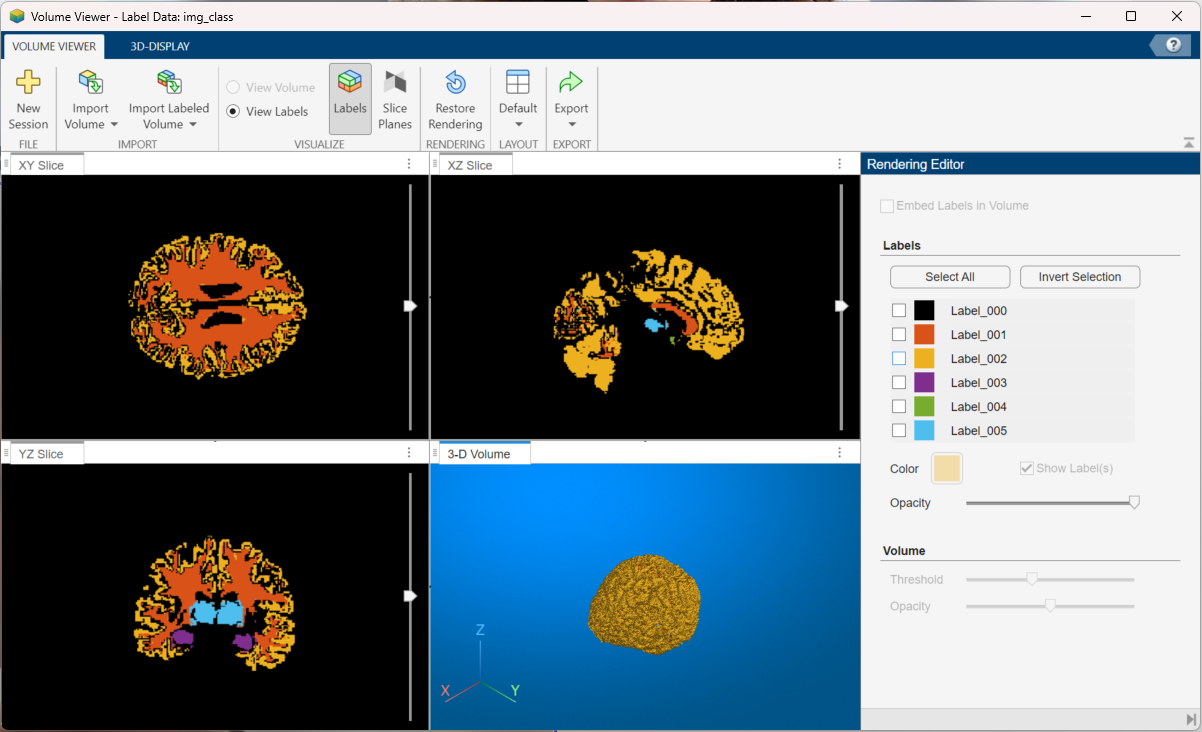

function tab_data=balanceTable(dataset)

    [Values,Categories]=histcounts(dataset.label);
    
    ind=Values==0;
    Values(ind)=[];
    Categories=Categories(~ind);
    % use the class with the lowest number of voxels as a the threshold for
    % the other classes.
    threshold=min(Values);
        
    tab_data=table;
    for n=1:length(Values)
        subset=randperm(Values(n),threshold);
        tab_class=dataset(dataset.label==Categories{n},:);
        tab_data=[tab_data; tab_class(subset,:)];
    end

end